## MAPS2001 project draft

# Analysis of Atmospheric Stable Water Isotopes and Related Movements of Air (Provisional Title)

## Abstract

*To be done later.*

## Introduction - NOT FINISHED

Since 1970's, there has been an increased interest in investigation of fractionation of the isotopes occuring in the components of water, i.e. $H^2$, $H^3$ and $O^{18}$. Most of the studies of these complex interactons between different parts of the atmosphere are based on the world wide survey organized since 1961 by the International Atomic Energy Ageney (IAEA) and the World Meteorological Organisation (WMO). The analysis of tritium abundance in different parts of the world can be related to proposing solutions to hydrological problems (e.g. predictions of lakes droought). 

https://en.wikipedia.org/wiki/Tritium

Furthermore, using the data for concentration of hydrogen and oxygen isotopes, it is possible to deduce various characteristics of the circulation patterns and mechanism of the global and local movements of water.

[3] W. Dansgaard, Stable isotopes in precipitation,Tellus XVI (1964), 4 November 1964.

**Section 1:**

Simple analysis of Valentia Observatory GNIP station data visualises the simple trends and correlations in abundances of deuterium, tritium and oxygen 18 isotopes in time following the original purpose of creation of the network of stations in the first place (in 1958), i.e. to monitor atmosheric fallout from nuclear tests during the Cold War.

Since the 1970’s it has been converted to support similar hydrological studies as shown in section 2 and 3, as both hydrogen and oxygen possess heavy isotopes that can be detected using this framework [1].

**Section 2:**

We found a paper investigating a possible correlation between climate and isotope concentration in precipitation:

*J. Lee, I. Fung, D. DePaolo, C. Henning, Analysis of the global distribution of water isotopes using the NCAR atmospheric general circulation model, Journal of Geophysical Research, Vol 112, D16306,  2007*

It states that the amount of deuterium per unit volume of precipitation linearly increases with the average annual temperature. This relationship, however, is said to hold only for regions with average annual temperatures of 15° or less, above this threshold, no correlation is observed.

**Section 3:**

The vertical structure of the atmosphere is a key ingredient for a better understanding of climate and weather patterns [1]. The way that water isotopes (2H, 3H, 18O) distribute vertically in the atmosphere can tell about various environmental variables, such as past temperatures and amounts of precipitation in the region [2]. Depending on whether the water isotopes are more abundant at the higher or lower altitudes, atmospheric profiles are categorised as top-heavy or bottom-heavy. Naturally, the precipitation is richer in heavier isotopes for the bottom-heavy profiles. In tropics, the concentration of the isotopes has a negative correlation with the amount of precipitation that falls and is termed “amount effect”. This is largely due to isotopic depletion as the condensation progresses [3]. It was found that vertical structures vary greatly from one geographic region to another.

The area of particular interest is the tropical Pacific ocean, which provides a large portion of evaporated water [2]. Interestingly, Eastern and Western Pacific have a different vertical structures. Although the whole region was believed to have top heavy profile, recent studies showed that Eastern pacific is more bottom heavy. The difference between the two structures might be the reason for large circulation of air masses in the Eastern Pacific [4]. Therefore, a better understanding of isotopes present within the region would help for evaluating the reasons for large atmospheric circulations in this region.

- repeat the analysis for the UK and possibly other regions

## Computational Methodology

**        1) Simple Initial Analysis of Data (Valentia GNIP Station)**

First, to understand the format and to visualize the data, the Valentia Observatory (Ireland) was randomly chosen. Simple analysis has been conducted.

IAEA WISER data for Valentia GNIP station was downloaded and imported to MATLAB.

clear all
clf
v = 'valentia.xlsx';

Readtable function was used to easily extract data from the Excel file.

s = readtable (v); % reading data from the specific Data File

IAEA WISER GNIP date were found to be not in a chronological order. To easily manipulate the data in general, the sorting function had to be invented and used.

%%% sort the data by date: %%%
allDates=s.Date(:); % gives all dates in one cell
A = datetime(allDates,'Format','yyyy-MM-dd'); % formats 'allDates' cell to an array datetime values

[sortDates,originalIndex]=sort(A); %sorts A array (708x1 - includes only dates) into ascending order.
                                  %originalIndex gives the original index or s table

sortedS=s(originalIndex,:); %print s table with originalIndex, which gives data in ascending date

The simple trends such as the variance of abundances of deuterium, tritium and oxygen with respect to time were plotted (scatter plot).

Saving measurements for deuterium, tritium and oxygen as variables:

% convenient labelling of variables
H2 = sortedS.H2;
H3 = sortedS.H3;
O18 = sortedS.O18;

Deuterium variance with respect to time:

figure (1)
scatter (sortDates, H2, 'ro', 'filled');
datetick('x','yyyy','keeplimits');
xlabel ('Date');
ylabel ('H2');
title ('Scatter plot of H2 variance wrt time')

Tritium variance with respect to time:

figure (2)
scatter (sortDates, H3, 'ro', 'filled');
datetick('x','yyyy','keeplimits');
xlabel ('Date');
ylabel ('H2');
title ('Scatter plot of H3 variance wrt time')

Oxygen variance with respect to time:

figure (3)
scatter (sortDates, O18, 'ro', 'filled');
datetick('x','yyyy','keeplimits');
xlabel ('Date');
ylabel ('O18');
title ('Scatter plot of O18 variance wrt time')

**    2. Comparison of isotope precipitation rate to average annual temperature word-wide and visualising possible correlation**

We found a paper investigating a possible correlation between climate and isotope concentration in precipitation:

*J. Lee, I. Fung, D. DePaolo, C. Henning, Analysis of the global distribution of water isotopes using the NCAR atmospheric general circulation model, Journal of Geophysical Research, Vol 112, D16306,  2007*

It states that the amount of deuterium per unit volume of precipitation linearly increases with the average annual temperature. This relationship, however, is said to hold only for regions with average annual temperatures of 15° or less, above this threshold, no correlation is observed.

In our first attempt to validate this hypothesis, we produced a scatterplot of local temperature as recorded in the GNIP data files against the isotope measurement. Again, we used the Valentia observatory as our first example:

% Investigating temperature dependence of isotope precipitation (scatter plot) for Valentia data

temp = sortedS.AirTemperature;

figure(4)
scatter (temp, H2, '*k')
xlabel('Temperature in °C');
ylabel('Delta D Deuterium')
axis square
box on
title ('Temperature versus Isotope Concentration for Valentia')

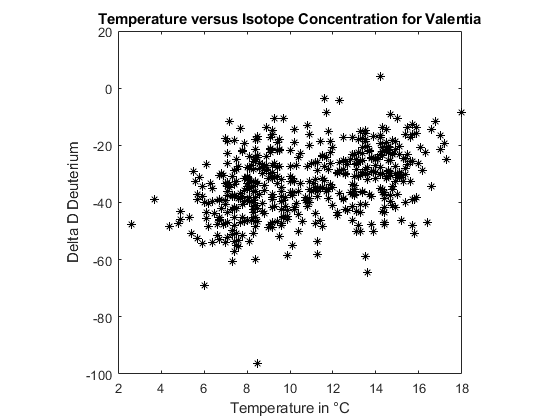

The resulting graph does not display and obvious correlation. This was to be expected, since the hypothesis is based on *average annual temperature*, not on the specific temperature at the time of precipitation. Instead of a weather dependence, it describes a correlation with the climate of a region, so in order to replicate the findings of our source paper, we need to compare geographically spread out data.

To do so, we chose six countries in different climate zones and uploaded their GNIP data into Matlab, along with climate data from the World Bank Group Climate Change Knowledge Portal ([http://sdwebx.worldbank.org/climateportal/index.cfm?page=downscaled_data_download&menu=historical](http://sdwebx.worldbank.org/climateportal/index.cfm?page=downscaled_data_download&menu=historical)):

s1 = readtable ('GeographicUK.xlsx'); % reading data from the specific Data File
s2 = readtable ('Greenland.xlsx');
s3 = readtable ('Spain.xlsx');
s4 = readtable ('Netherlands.xlsx');
s5 = readtable ('Norway.xlsx');
s6 = readtable ('Syria.xlsx');

t1 = readtable('GeographicUK_AAT.xls');
t2 = readtable('Greenland_AAT.xls');
t3 = readtable('Spain_AAT.xls');
t4 = readtable('Netherlands_AAT.xls');
t5 = readtable('Norway_AAT.xls');
t6 = readtable('Syria_AAT.xls');

We then calculated the mean and medium values of temperature and isotope precipitation for all three species. Note that while the data for deuterium and oxygen-18 is already given as delta D values, Tritium is given in TU (Tritium Units, one Tritium atom in 1018 hydrogen atoms), so we had to convert the tritium data into delta D before we display the results:

%means and medians of H2, H3, O18 and temperature for different locations
means=[mean(s1.H2,'omitnan'), mean(s1.H3,'omitnan'), mean(s1.O18,'omitnan'), mean(t1.tas,'omitnan')];
medians=[median(s1.H2,'omitnan'), median(s1.H3,'omitnan'), median(s1.O18,'omitnan'), median(t1.tas,'omitnan')];

means=[means;mean(s2.H2,'omitnan'), mean(s2.H3,'omitnan'), mean(s2.O18,'omitnan'), mean(t2.tas,'omitnan')];
medians=[medians;median(s2.H2,'omitnan'), median(s2.H3,'omitnan'), median(s2.O18,'omitnan'), median(t2.tas,'omitnan')];

means=[means;mean(s3.H2,'omitnan'), mean(s3.H3,'omitnan'), mean(s3.O18,'omitnan'), mean(t3.tas,'omitnan')];
medians=[medians;median(s3.H2,'omitnan'), median(s3.H3,'omitnan'), median(s3.O18,'omitnan'), median(t3.tas,'omitnan')];

means=[means;mean(s4.H2,'omitnan'), mean(s4.H3,'omitnan'), mean(s4.O18,'omitnan'), mean(t4.tas,'omitnan')];
medians=[medians;median(s4.H2,'omitnan'), median(s4.H3,'omitnan'), median(s4.O18,'omitnan'), median(t4.tas,'omitnan')];

means=[means;mean(s5.H2,'omitnan'), mean(s5.H3,'omitnan'), mean(s5.O18,'omitnan'), mean(t5.tas,'omitnan')];
medians=[medians;median(s5.H2,'omitnan'), median(s5.H3,'omitnan'), median(s5.O18,'omitnan'), median(t5.tas,'omitnan')];

means=[means;mean(s6.H2,'omitnan'), mean(s6.H3,'omitnan'), mean(s6.O18,'omitnan'), mean(t6.tas,'omitnan')];
medians=[medians;median(s6.H2,'omitnan'), median(s6.H3,'omitnan'), median(s6.O18,'omitnan'), median(t6.tas,'omitnan')];

According to the  reference *G. Torri, D. Ma, Z. Kuang Stable water isotopes and large-scale vertical motions in the tropics, Journal of Geophysical Research: Atmospheres Volume 122, Issue 7, pages 3703-3717, 2017 *on page 3707, the abundance of an isotope is measured with the following formula:


$$\delta D=\left(\frac{R_{\mathrm{sample}} }{R_{\mathrm{VSMOW}} }-1\right)\cdot 1000\text{ }‰$$


where:

$R_{\mathrm{sample}}$ is the ratio of the isotope to the common, stable isotope of hydrogen in the samples considered,

 $R_{\mathrm{VSMOW}}$ is the same ratio but for a reference sample with the isotopic composition of the Vienna standard mean ocean water.


$$R_{\text{VSMOW}} =1\ldotp 85\pm 0\ldotp 36\times {10}^{-11} \text{ }\mathrm{ppm}$$
 

% The H3 abundance is not given in Delta D, but in TU (Tritium atoms per 1018 Hydrogen atoms), so Delta D must be calculated:
vsmow=1.85*10^-11;   %Given in ppm 
means(:,2)=((means(:,2).*(1/1018)./vsmow)-1).*1000
medians(:,2)=((medians(:,2).*(1/1018)./vsmow)-1).*1000;

 Next we viewed our sample in form of scatterplots:

%Plot scatterplots of isotope concentration in precipitation vs temperature

scatter(means(:,4),means(:,1));     %H2 mean values
xlabel('Average Temperature in °C');
ylabel('Delta H2 (means)');
title('Climate Dependence of H2 Concentration');

scatter(medians(:,4),medians(:,1));     %H2 median values
xlabel('Average Temperature in °C');
ylabel('Delta H2 (medians)');
title('Climate Dependence of H2 Concentration');

scatter(means(:,4),means(:,2));     %H3 mean values
xlabel('Average Temperature in °C');
ylabel('Delta H3 (means)');
title('Climate Dependence of H3 Concentration');

scatter(medians(:,4),medians(:,2));     %H3 median values
xlabel('Average Temperature in °C');
ylabel('Delta H3 (medians)');
title('Climate Dependence of H3 Concentration');

scatter(means(:,4),means(:,3));     %O18 mean values
xlabel('Average Temperature in °C');
ylabel('Delta O18 (means)');
title('Climate Dependence of O18 Concentration');

scatter(medians(:,4),medians(:,3));     %O18 median values
xlabel('Average Temperature in °C');
ylabel('Delta O18 (medians)');
title('Climate Dependence of O18 Concentration');

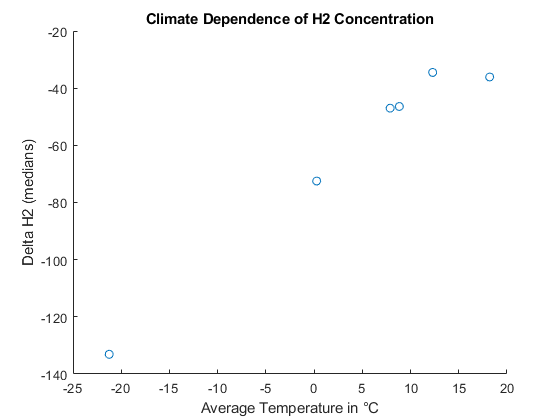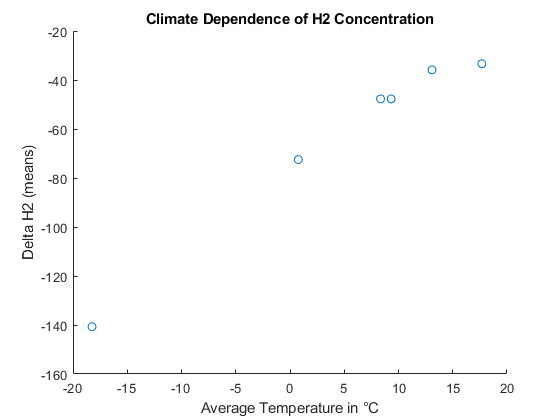

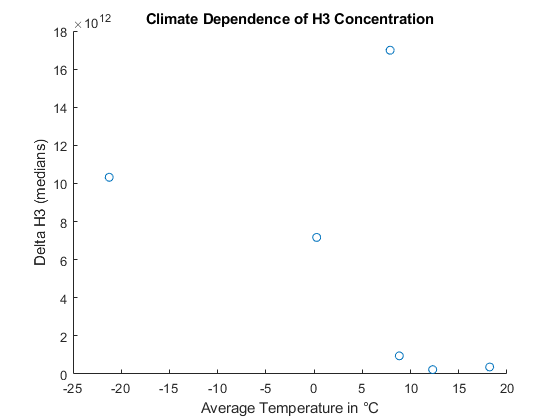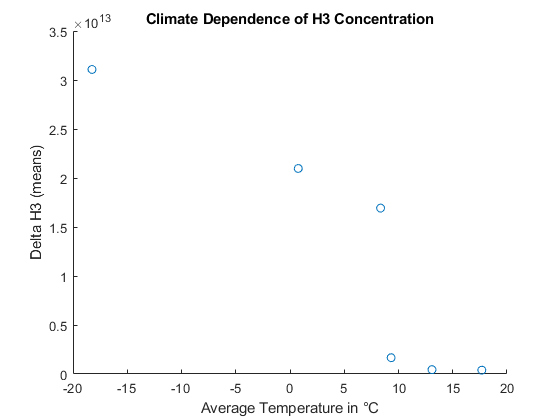

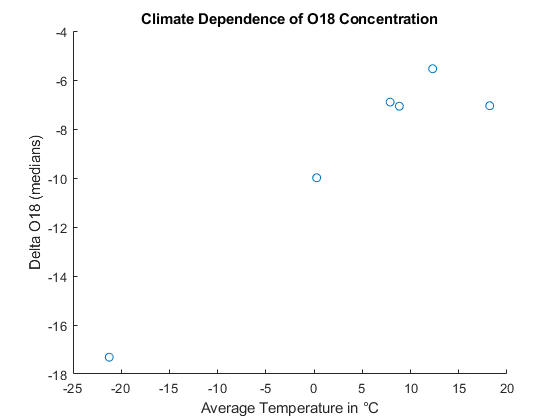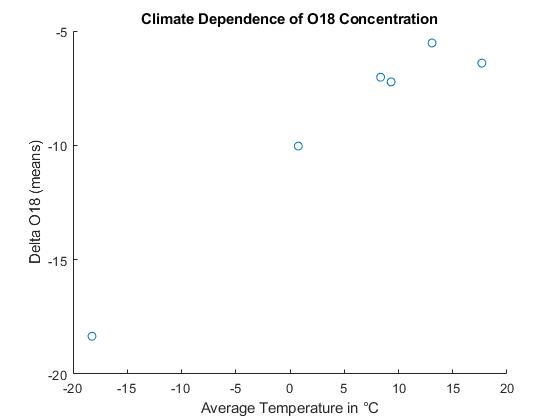

We can see the exact dependence as described in the reference paper for deuterium and oxygen-18, but no dependence for tritium. This might be because of the high tendency of tritium samples to get contaminated, it is stated on the IAEA WISER website that the measurements for tritium often return values significantly higher than expected.

To fully validate the temperature dependence, we needed to significantly increase our sample size. For this purpose we developed a method to load whole folders of excel files into a cell array instead of uploading each table individually. The source directory has to be adjusted by each user, but this procedure enables us to sample almost the whole GNIP Database:

%The following path has to be adjusted for each computer!!!!!
source_dir = 'D:/A_Karos Kram/Studium England/Year2/MAPS2001/1project/MATLAB-Isotopes-master/MATLAB-Isotopes-master/DRAFT/Database/';

%Load all .xls files (the climate data) into one cell array
source_files = dir(fullfile(source_dir, '*.xls'));
AATdata=cell(size(source_files));

for i = 1:length(source_files)
  AATdata{i} = readtable(fullfile(source_dir, source_files(i).name));
end

%Load all .xlsx files (the Isotope data) into one cell array
moresource_files = dir(fullfile(source_dir,'*.xlsx'));
Isotopedata=cell(size(moresource_files));
for j = 1:length(moresource_files)
  Isotopedata{j} = readtable(fullfile(source_dir, moresource_files(j).name));
end

Since all data tables are now saved in one cell array, we can calculate the means and medians in a simple loop:

%Calculate the means and medians for H2, H3, O18 and Temperature across all datasets
means=zeros(size(Isotopedata,1),4); %creates arrays full of zeros of the right size
medians=zeros(size(Isotopedata,1),4);

for i= 1:length(Isotopedata)
    
   activedata=Isotopedata{i,1};                    
   tempdata=AATdata{i,1};
   
   means(i,1)=mean(activedata.H2, 'omitnan');       %Means for the isotopes
   means(i,2)=mean(activedata.H3, 'omitnan');
   means(i,3)=mean(activedata.O18, 'omitnan');
                                                
   medians(i,1)=median(activedata.H2, 'omitnan');   %Medians for the Isotopes
   medians(i,2)=median(activedata.H3, 'omitnan');
   medians(i,3)=median(activedata.O18, 'omitnan');
                    
   means(i,4)=mean(tempdata.tas, 'omitnan');        %Means for temperatures
    
   medians(i,4)=median(tempdata.tas, 'omitnan');    %Medians for temperatures
   
end  

After converting the units for tritium, the bigger representative samples are plotted, again as a scatterplot:

% The H3 abundance is not given in Delta D, but in TU (Tritium atoms per 1018 Hydrogen atoms), so Delta D must be calculated:
vsmow=1.85*10^-11;   %Given in ppm 
means(:,2)=((means(:,2).*(1/1018)./vsmow)-1).*1000;
medians(:,2)=((medians(:,2).*(1/1018)./vsmow)-1).*1000;


%Plot scatterplots of isotope concentration in precipitation vs temperature

scatter(means(:,4),means(:,1));     %H2 mean values
xlabel('Average Temperature in °C');
ylabel('Delta H2 (means)');
title('Climate Dependence of H2 Concentration');

scatter(medians(:,4),medians(:,1));     %H2 median values
xlabel('Average Temperature in °C');
ylabel('Delta H2 (medians)');
title('Climate Dependence of H2 Concentration');

scatter(means(:,4),means(:,2));     %H3 mean values
xlabel('Average Temperature in °C');
ylabel('Delta H3 (means)');
title('Climate Dependence of H3 Concentration');

scatter(medians(:,4),medians(:,2));     %H3 median values
xlabel('Average Temperature in °C');
ylabel('Delta H3 (medians)');
title('Climate Dependence of H3 Concentration');

scatter(means(:,4),means(:,3));     %O18 mean values
xlabel('Average Temperature in °C');
ylabel('Delta O18 (means)');
title('Climate Dependence of O18 Concentration');

scatter(medians(:,4),medians(:,3));     %O18 median values
xlabel('Average Temperature in °C');
ylabel('Delta O18 (medians)');
title('Climate Dependence of O18 Concentration');

Graphs can be seen in the discussion.

**        3.1 Reproduction of a Graph from the Main Reference **$\delta D$** vs. precipitation rate**

To reproduce some of the analysis in tropics according to the main reference:

*G. Torri, D. Ma, Z. Kuang Stable water isotopes and large-scale vertical motions in the tropics, Journal of Geophysical Research: Atmospheres Volume 122, Issue 7, pages 3703-3717, 2017, *

the plot from page 3714: $\delta D$ vs. precipitation rate was replotted in order to produce a piece of code with same/similar results. The data from IAEA WISED database for West and East Pacific was donwloaded accordingly:

**West:** (15° N - 15° S, 120° E - 180° E): Darwin, Jayapura, Madang, Tarawa, Truk, Yap

**East**: (15° N - 15° S, 180° E - 240° E): Apia, Canton Island, Christmas Island

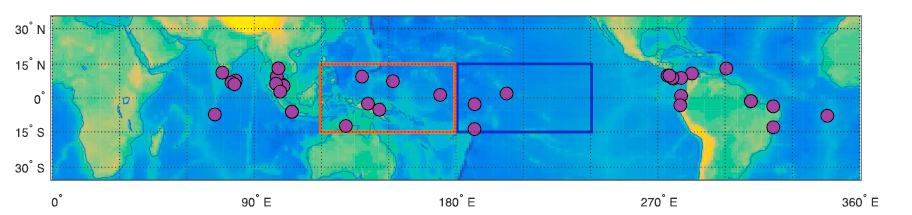

% reproduced graph from the main reference
% precipitation rate for Eastern and Western Pacific

clear all
clf
% WEST
wt1 = 'WDarwin.xlsx'; % Darwin
wt2 = 'WJayapura.xlsx'; % Jayapura
wt3 = 'WMadang.xlsx'; % Madang
wt4 = 'WTarawa.xlsx'; % Tarawa
wt5 = 'WTruk.xlsx'; % Truk
wt6 = 'WYap.xlsx'; % Yap

% EAST
et1 = 'EApia.xlsx'; % Apia
et2 = 'ECanton_Island.xlsx'; % Canton Island
et3 = 'EChristmas_Island.xlsx'; % Christmas Island

Using readtable function:

% reading data from the specific Data File

% WEST
w1 = readtable (wt1);
w2 = readtable (wt2);
w3 = readtable (wt3);
w4 = readtable (wt4);
w5 = readtable (wt5);
w6 = readtable (wt6);

% EAST
e1 = readtable (et1);
e2 = readtable (et2);
e3 = readtable (et3);

The data is not chronological: use of sorting function. The loop to run over all the datasets will be used.

% WEST sort the data by date:
% w1 Darwin
allDatesw1=w1.Date(:); % gives all dates in one cell
Aw1 = datetime(allDatesw1,'Format','yyyy-MM-dd'); % formats 'allDates' cell to an array datetime values

[sortDatesw1,originalIndex]=sort(Aw1); %sorts A array (708x1 - includes only dates) into ascending order.
                                  %originalIndex gives the original index or s table

sortedw1=w1(originalIndex,:); %print s table with originalIndex, which gives data in ascending date

% w2 Jayapura
allDatesw2=w2.Date(:);
Aw2 = datetime(allDatesw2,'Format','yyyy-MM-dd'); 
[sortDatesw2,originalIndex]=sort(Aw2);

sortedw2=w2(originalIndex,:);

% w3 Madang
allDatesw3=w3.Date(:);
Aw3 = datetime(allDatesw3,'Format','yyyy-MM-dd'); 
[sortDatesw3,originalIndex]=sort(Aw3);

sortedw3=w3(originalIndex,:);

% w4 Tarawa
allDatesw4=w4.Date(:);
Aw4 = datetime(allDatesw4,'Format','yyyy-MM-dd'); 
[sortDatesw4,originalIndex]=sort(Aw4);

sortedw4=w4(originalIndex,:);

% w5 Truk
allDatesw5=w5.Date(:);
Aw5 = datetime(allDatesw5,'Format','yyyy-MM-dd'); 
[sortDatesw5,originalIndex]=sort(Aw5);

sortedw5=w5(originalIndex,:);

% w6 Yap
allDatesw6=w6.Date(:);
Aw6 = datetime(allDatesw6,'Format','yyyy-MM-dd'); 
[sortDatesw6,originalIndex]=sort(Aw6);

sortedw6=w6(originalIndex,:);

% EAST sort the data by date:
% e1 Apia
allDatese1=e1.Date(:);
Ae1 = datetime(allDatese1,'Format','yyyy-MM-dd'); 
[sortDatese1,originalIndex]=sort(Ae1);

sortede1=e1(originalIndex,:);

% e2 Canton Island
allDatese2=e2.Date(:);
Ae2 = datetime(allDatese2,'Format','yyyy-MM-dd'); 
[sortDatese2,originalIndex]=sort(Ae2);

sortede2=e2(originalIndex,:);

% e3 Christmas Island
allDatese3=e3.Date(:);
Ae3 = datetime(allDatese3,'Format','yyyy-MM-dd'); 
[sortDatese3,originalIndex]=sort(Ae3);

sortede3=e3(originalIndex,:);

We would first like to reproduce figure 10  from* Torri, G., D. Ma, and Z. Kuang (2017), Stable water isotopes and large-scale vertical motions in the tropics, J. Geophys. Res. Atmos., 122, *where precipitation rate per day is plotted against $\delta D$.

We first want to concatenate all our data from our two areas, in ordr to find general trends for East and West. To do this, wewant to remove the comment column, as some of the downloaded station data has no data in this column, and so the column does not exist in the data when converted to a table. This only affects the West data, so we now removed the coment column from this data. However, if we run this section again without re-importing the western datasets, MatLab wont understand the non-existance of this variablem so we only do this if the data actuall exists (if it exists for w1, we assume it exists for all)

clf

The data is concatenated from the various western and eastern stations.

We also set some figure numbers, as we want to be able to refer back to a certain graph when specifying certain properties and data.

wFull=[w1;w2;w3;w4;w5;w6]; % concatenating the data from the various western stations
eFull=[e1;e2;e3]; % doing the same for east
figureNumScatter=10;
figureNumBins=20; 
% setting figure numbers for the two graphs

The loop is used to plot the graphs twice, switching between east and west each time.

for j=[1,2]
 if j==1
     % for the Eastern Loop
     s=eFull;
     pointColour='xblack';
     
 else
     % Western loop
     s=wFull;
     pointColour='xb';
     
 end

Next, the relevant data is retrieved. As we want precipitation per day, and months are different lengths, we calculate the number of days each reading was taken over, and use this to determine the average precipitation per day (note that we have to do this via dividing total precipitation by number of days, as we do not have any more temporal resolution than this.

%retrieving relevant data
d=datenum(s.Date,'yyyy-mm-dd');
H3=s.H3;
H2=s.H2;
O18=s.O18;

% days in month
numdays=(datenum(s.EndOfPeriod, 'yyyy-mm-dd')- datenum(s.BeginOfPeriod,'yyyy-mm-dd')+1);

% precipitation per day
pppday=s.Precipitation./numdays;

First, the scatter plot is plotted to visualize the unbinned data first and to decide on the bin size.

% see a scatter plot of the data
figure(figureNumScatter)
hold on
plot(pppday,H2,pointColour)
hold off
xlabel('Precipitation rate (mm per day)')
ylabel('\delta D')

In the figure we are trying to reproduce, they use bins of 5, so we will as well. However, we see that their final bin stretches to infinity, so we will see if we can incorporate this as well.

% deciding our bin sizes
Edges=[0,5,10,15,20,Inf];

To do these steps, we must discretize the $\delta D$ data by its relevant precipitation per day data.


% finding out which deltaH2s fall in each ppt/day
[pppdaybin,Edge]= discretize(pppday,Edges);

% pppdaybin= which 'bin' each pppday in the array falls in
% to get the array of deltaH2 for each bin

We then use a loop in order to sparate out each binned set of data

for i=1:(length(Edge)-1)
    
% using a structure as it is easier to use with loops
% making the struct separated by bin

H2binned(i).H2=H2(pppdaybin == i);
end

And we use another loop in order to find the means for each bin

for i=1:(length(Edge)-1)
% finding the mean of these binned deltaH2 (along with the standard deviations)
    H2binned(i).mean = nanmean(H2binned(i).H2);
    H2binned(i).error = nanstd(H2binned(i).H2);
end

Whilst structures generally work more quickly with loops, arrays are slightly easier to do basic data manipulation with, so we quickly convert the data back into an array

for i=1:(length(Edge)-1)
% switching these back to an array, so we can more conveniently use this data (ouside of loops)
    H2binnedmeans(i)=H2binned(i).mean;
    H2binnedmeanserror(i)=H2binned(i).error;
end

As we are trying to reproduce figure 10, and so would be plotting the mean $\delta D$ binned, versus the midvalue of each bin, we first need to find the midvalue. (Note for the last bin, we just add the first bins mid-value to the beggining of the last bins first edge, as the last bi stretches all the way to infinity)

% getting an array of the midvalues and creating an array of the start and end points of each bin, and then mean them

MidEdge(1,:)=Edge(1:(length(Edge)-1));
MidEdge(2,:)=Edge(2:length(Edge));
MidEdge=mean(MidEdge);
%Redefining the mid edge for the final bin
MidEdge(length(Edge)-1)=MidEdge(1)+Edge(length(Edge)-1);


Plotting the bar graph $\delta D$ vs. precipitation rate. We use the bar function to produce similar bars as in figure 10. We also do not want the bars to overlay each other, so adjust their position depending on which loop cycle we are on

% plotting the graph, and use 'bar' function to plot as bars (as in the original paper)

if j==1
% shifting the bars for the first loop (East) to the positive
    MidEdgeShift=-1;
else
% and the bars for the second loop (West) to the negative
    MidEdgeShift=1;
end 
% plotting a bar graph
figure(figureNumBins)

Here we decided to try to make the graph a little prettier

% including earlier calculated shift
pointPosn=MidEdge+MidEdgeShift;
hold on

% creating a bar object so we can edit its properties
b(j)=bar(pointPosn,H2binnedmeans);

% We adjust its width to allow us to see both bars at once
b(j).BarWidth=0.4;

%We also want to include errors, so we create an error bars object
e=errorbar(pointPosn,H2binnedmeans,H2binnedmeanserror);
%And remove the line and points (as we already have our bars
e.LineStyle='none';
e.Marker='none';


And include all necesary details for a graph (title, axes labels, etc)

title ('Delta Deuterium vs. Precipitation Rate: Bar Graph')

xlabel('Precipitation rate (mm per day)')
ylabel('\delta D (per mil)')
xticklabels([0,5,10,15,20,Inf])
xlim([0,25])
grid on
hold off

end
legend (b,'Eastern Stations', 'Western Stations', 'Location', 'southwest' )


The next step is to repeat the same analysis for other isotopes, the UK and other geographic regions. 

 **3.2 Generalising the code and making it more efficient  (to be incorporated in section 3)**

The final goal is to make the analysis (code) applicable to different datasets and therefore enables comparison between various geographical regions.

In order to achieve that, repetitive sections of the code will be rewrtiten into the loop structure. So far, the code works with numerical array structures. However, to incorporated loops, the data will need to be stored in cell structures (one nested cell) since the datafiles for each station in the IAEA/GNIP database have different dimensions.

After conversion to cell type, there is a need to extract the indes of specific information (the column number for date, mixing ratios of water isotopes).To make the code more efficient, the variables were assigned outside the loops, wherever possible, to avoid redefining the variable.

To sort the data in chronological order:

columnNames=w1.Properties.VariableNames % extracting column names
% (needed for getting specific data like 'Date' etc)

convertwt{1}=table2cell(w1); %
convertwt{2}=table2cell(w2); % convert all of those to cell so we can
convertwt{3}=table2cell(w3); % put them together into one bigger cell
convertwt{4}=table2cell(w4);
convertwt{5}=table2cell(w5);
convertwt{6}=table2cell(w6);
convertwt{7}=table2cell(e1);
convertwt{8}=table2cell(e2);
convertwt{9}=table2cell(e3);

% the loop which imports all data automatically is yet
% to be implemented

re_st=string(columnNames) % convert column names cell to readable string
date_index=find(strcmp(re_st,'Date')) % finds the index of the 'Date' - 
    % can be used for finding any name of the column
   
% loop to sort the data according to the date.
    
for i=1:length(convertwt)
    tempVar=convertwt{i}; % create new variable just for convenience
                        % - so to store the value all_data(i) and
                        % avoid double indexing, which is the 
                        % problem in the last line (sorted{i}=...)
    allDatesofList_i=tempVar(:,date_index); % gives all dates in one cell
    dating_i = datetime(allDatesofList_i,'Format','yyyy-MM-dd'); % formats 
    % 'allDates' cell to an array datetime values

    [sortDates_i,originalIndex_i]=sort(dating_i); %sorts A array (708x1
    % - includes only dates) into ascending order. 
    % originalIndex gives the original index or s table

    sorted{i}=tempVar(originalIndex_i,:) %print s table with originalIndex, 
    % which gives data in ascending date
end

To calculate delta deuterium using a loop:

% delta D versus precipitation rate per day

prec_index=find(strcmp(re_st,'Precipitation')) % finds the index for precipitation
H2_index=find(strcmp(re_st,'H2')) % finds the index for H2
graphdata={} % this is where we will store our data - for now empty,
% but it will be a nested cell
for i=1:length(convertwt)
    % creates a cell, which stores precipitation in rows, H2 in columns
    deltaDprecip{i} = [sorted{i}(:,prec_index), sorted{i}(:,H2_index)]
    % delete NaN rows:
    % 1. For rmmising to work, the cell needs to be converted to double array:
    ctm = rmmissing(cell2mat(deltaDprecip{i}));
    % 2. Next, we need to convert it back to cell:
    nc_graphdata=mat2cell(ctm,[size(ctm,1)]) % next cell in graph data
    graphdata=[graphdata, nc_graphdata] % append the cell to the overall 
    % 'graphdata' cell
end

After the loop is fully integrated into the code, the separate parts of the loop will be isolated into separate functions, which would leave the final code considerably shorter, easier to analyse and understand.

However, so far the difficulty was to design a function which accepts cell data type as input.

## Critical Discussion of Results

**        1) Simple Initial Analysis of Data (Valentia GNIP Station)**

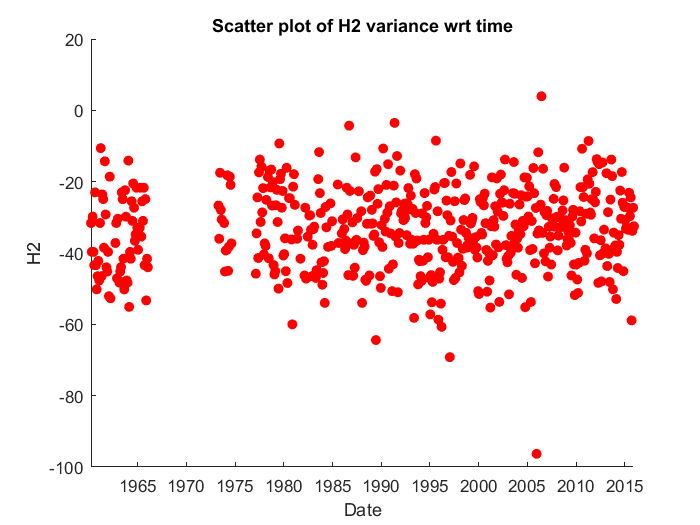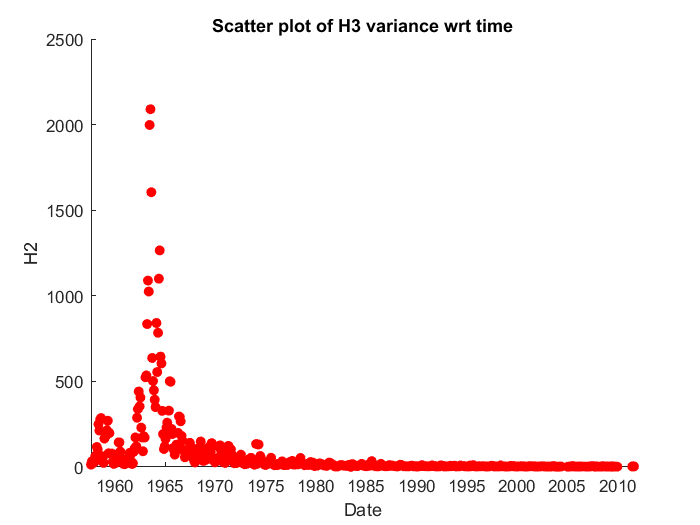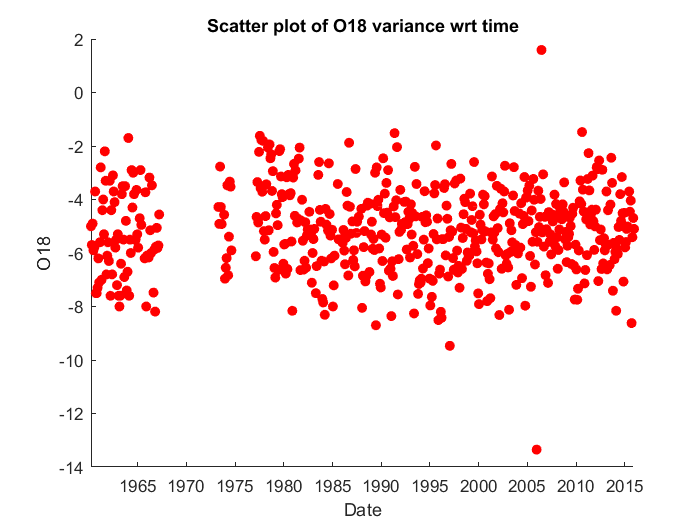

Discussion:

For deuterium and oxygen 18:

- abundances of deuterium and oxygen 18 stable; potential outliers in 2005

- Valentia 2005: warmest and wettest place in Ireland  - correlation?

- possible future work to provide thorough analysis of deuterium and oxygen abundances dependence on temperature

- missing data in late sixties and early seventies

H3:

- obvious trend: nonstandard and very high abundance of tritium around 1965

- detecting atmospheric fallout from nuclear tests during the Cold War

- tritium production is an essential to the type of fusion used in weapons (https://en.wikipedia.org/wiki/Nuclear_weapon_design#Tritium_production)

- thus a rapid increase of the abundance of tritium in the atmosphere

**        2)  Comparison of isotope precipitation rate to average annual temperature word-wide and visualising possible correlation**

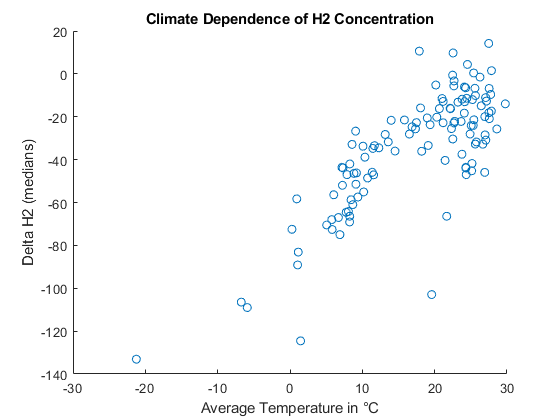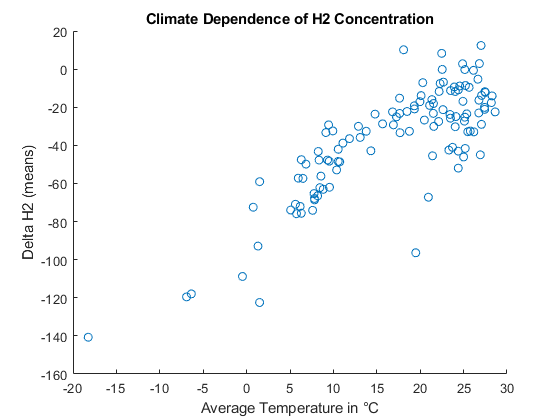

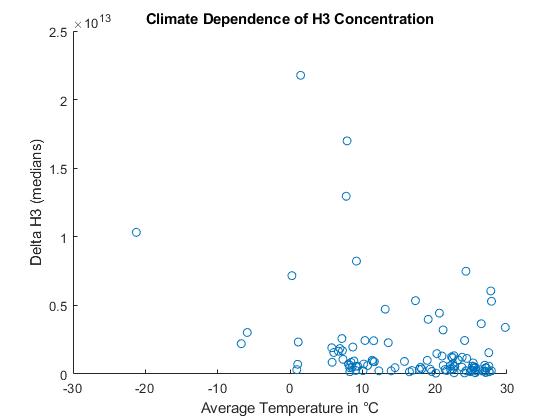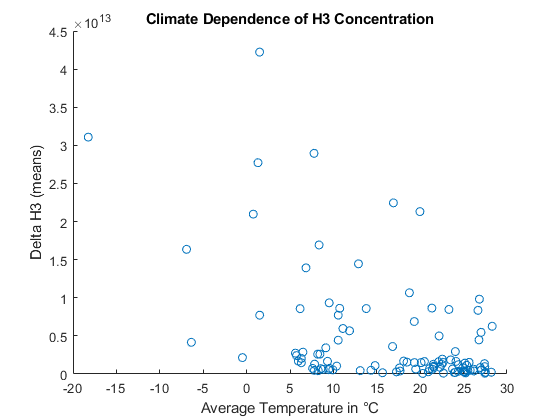

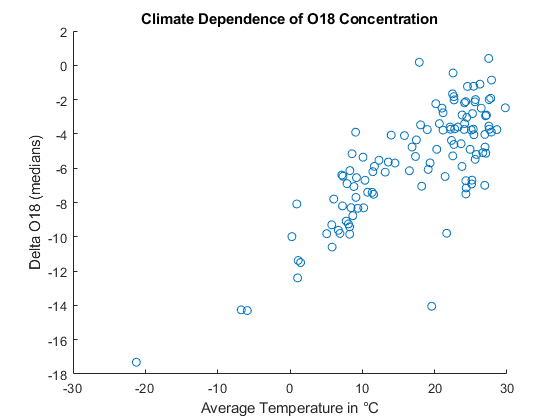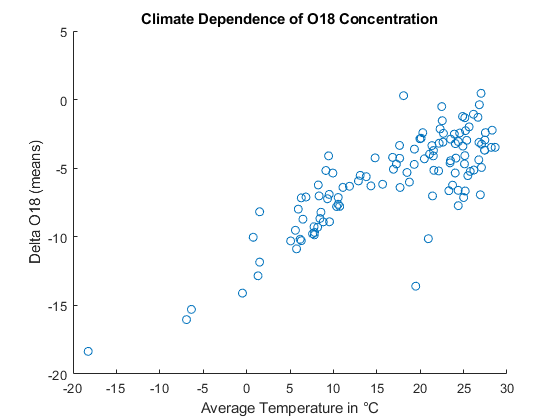

The so far produced scatterplots look like they validate the correlation described in the reference, although the variance seems quite high. This stems from the measures we took to simplify our task: 

- While the Isotope values are recorded at usually only a few locations per country the average temperature is given for the whole country - should we use the climate data given in the GNIP files?

- We neglected the size of the countries and summarised each one to one data point, which causes large errors for countries like the USA or Russia, that potentially span several climate zones -for increased precision, data should be grouped in smaller bins or by climate zone

- The annual temperature is (with a few exceptions) averaged over 30 years between 1960 and 1990, while part of measurements are from recent decades. Maybe climate change distorted the relationship under these conditions

- Some countries have stations in locations that are allocated to a certain country in the GNIP database and therefore went into our calculations for this country, although they geographically lie in an entirely different climate zone (example: Saint Helena in the South Altlantic Ocean provides misleading measurements for a 'UK climate')

What does this correlation stem from? The paper expresses the theory that the isotopes precipitate easily in warm environments. By the time the atmospheric water reaches colder regions like the artic/antarctic, there is simply no isotopes left to precipitate.  (*This is not the full discussion, after the coding part of the section is completed we will compare our results carefully to the paper and explain phenomena)*

Why is there no correlation found for Tritium?

Tritium is naturally only present in extremely small quantities in the atmosphere ($R_{\text{VSMOW}} =1\ldotp 85\pm 0\ldotp 36\times {10}^{-11} \text{ }\text{ppm}$), so the smallest contamination by human caused atomic activity can alter the natural patterns significantly.

**        3) Reproduction of the Graph from the Main Reference **$\delta D$** vs. precipitation rate**

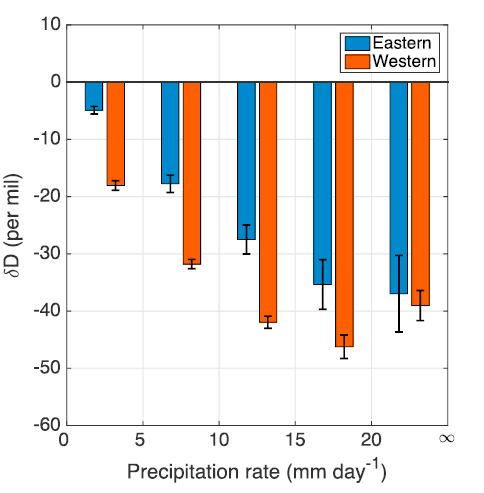

Our reproduced graph temporarily was similar, although had som obvious differences:

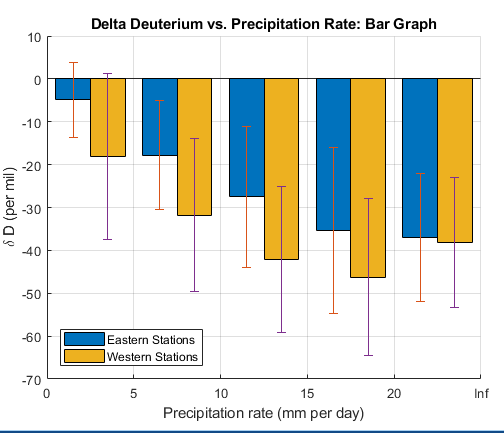

Discussion: 

The main differences are the error bars being significantly different in magnitude - possible reasons for this include:

- Different way of calcuklating error

- Error values are in different units/magnitudes to those assumed

Other differences include

- different date range, i.e. newest datasets included in our graph- however, this does not seem to have affected the dataset's mean significantly

- potentially different methodology - although this should still produce same results

## Conclusions and Future Work

**Conclusions**: *To be done later.*

**Future work:**

- include the investigation of the data sets from tropics for Tritium and Oxygen 18 isotopes

- for Valentia and other areas: provide thorough analysis of deuterium and oxygen abundances dependence on temperature

- reproduce the results for the UK, i.e. expand the analysis to other non-tropic regions

For project part 2)Temperature Dependence:

Check whether GNIP temperatures provide a smaller variance for the correlation

Plot only the temperature range where the relationship holds (<15°C) and plot a line of best fit. Determine the variance. 

Use the mapping toolbox to visualise both datasets (Isotope concentration and temperature) on a world map. Reproduce the map from the reference where the difference between relative temperature and relative Isotope concentration is depicted. (Might not have time for this, would be future work) Determine regions beside the tropics where the correlation does not hold.

## References

- G. Torri, D. Ma, Z. Kuang Stable water isotopes and large-scale vertical motions in the tropics, Journal of Geophysical Research: Atmospheres Volume 122, Issue 7, pages 3703-3717, 2017.

- J. Lee, I. Fung, D. DePaolo, C. Henning, Analysis of the global distribution of water isotopes using the NCAR atmospheric general circulation model, Journal of Geophysical Research, Vol 112, D16306,  2007.

- W. Dansgaard, Stable isotopes in precipitation,Tellus XVI (1964), 4 November 1964.

- Galewsky, J., H. C. Steen-Larsen, R. D. Field, J. Worden, C. Risi, and M. Schneider, Stable isotopes in atmospheric water vapor and applications to the hydrologic cycle, Rev. Geophys., 54, pages 809–865, 2016.

- Sutanto, S. J., G. Hoffmann, J. Worden, R. A. Scheepmaker, I. Aben, and T. Röckmann, Atmospheric processes governing the changes in water isotopologues during ENSO events from model and satellite measurements, J. Geophys. Res. Atmos., 120, pages 6712–6729, 2015.

- World Bank Group Climate Change Knowledge Portal ([http://sdwebx.worldbank.org/climateportal/index.cfm?page=downscaled_data_download&menu=historical](http://sdwebx.worldbank.org/climateportal/index.cfm?page=downscaled_data_download&menu=historical)):

-  IAEA/WMO Global Network of Isotopes in Precipitation (GNIP) database: [http://www-naweb.iaea.org/napc/ih/IHS_resources_gnip.html](http://www-naweb.iaea.org/napc/ih/IHS_resources_gnip.html)

**Requested feedback:**

- Structure: after abstract and introduction, should we divide the report in three sections (Simple Analysis, Temperature Dependence, Reproduction of Reference Graph), each with their own discussion, conclusion and future work section?

- Is the general amount of computing/analising (including what we still plan to do before the deadline, see future work) sufficient for the project?

- In terms of being concise: What needs to be included, where can we cut down? Should we display the 'evolution' of the project, graphs that didn't depict the right information but led us on the right track? Do we have to include all code or can we describe what it does if it's very simple/has been shown previously in the report? If we use an unrefined code to plot something and refined the method for a later example of similar analysis, do we stil have explain the worse method first?

- Is our treatment of the Tritium units correct?

- Is it ok to comment the code with comments in the code instead of explaining everything in texttbreaks? How detailed does the code explanation have to be (things like when calculating the mean, we omit NaN values...)

- Should we write in third person, or writing in first person is also fine?

- Each of us wrote different parts, are the differences between style/way of writing in different parts very noticeable

- ....and anything else you thing will cost us marks :-)